clear;
close all;
clc;

1) Simulating laser ultrasonic pulse with pulse duration variable

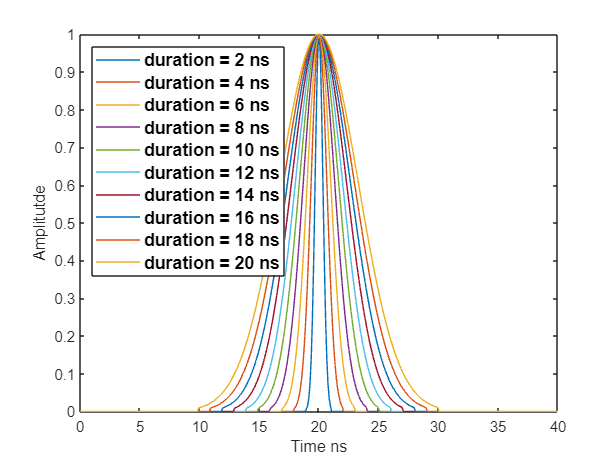

T = 1/50e3;
dMax = 20;
dArrayPlot = linspace(2,dMax,10);
dArray = dArrayPlot./1e9;
dMax = dMax./1e9;

figure;

for n =1 :length(dArray)
    d = dArray(n);
    Fs = 1e10;                          % target frequency 200 MHz, fs = 400Hz is enough, here we want get smooth frequency curve.
    pts = 2*dMax*Fs;                    % points of sampling,10 times the time duration;
    
    t = linspace(0,2*dMax,pts);
    p = zeros(1,length(t));
    
    ptsPulse = Fs*d;                    % duration points
    pulse_start = pts/2 - ptsPulse/2;
    pulse_end = pts/2 + ptsPulse/2;
    
    p(pulse_start:pulse_end) = 1;

    number_of_points = length(t);
    
    peak_pos_fract = ((pulse_start+pulse_end)/2)/pts;
    half_width_fract = ((pulse_end-pulse_start)/2)/pts;
    filter = fn_gaussian(number_of_points, peak_pos_fract, half_width_fract);
    filtered_pulse = filter'.*p;

    figure(1);
    str = ['duration = ',num2str(dArrayPlot(n)), ' ns'];
    plot(t*1e9,filtered_pulse,'DisplayName',str);
    xlabel('Time ns')
    ylabel('Amplitutde')
    hold on

    spectrum = fft(filtered_pulse,pts);
    spectrum = abs(spectrum)/max(abs(spectrum));
    f=Fs*(0:pts-1)/pts;

    
    figure(2);
    str = ['duration = ',num2str(dArrayPlot(n)), ' ns'];
    plot(f(1:pts/40)*1e-6, spectrum(1:pts/40),'DisplayName',str);
    xlabel('Frequency MHz')
    ylabel('Amplitutde')
    hold on
end

figure(1);
legend('Fontsize',12,'Location','northwest','FontWeight','bold');

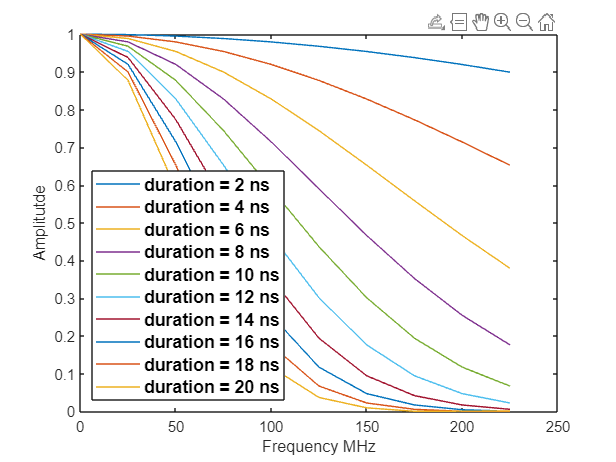


figure(2);
legend('Fontsize',12,'Location','southwest','FontWeight','bold');